# ROZWIAZYWANIE UKŁADÓW RÓWNAŃ LINIOWYCH

## Ogólne zagadnienia wymagane na laboratorium nr 1

## "Wstęp do metod numerycznych"

Opracował: K. Król

**---------------------------------------------------------------------------------------------------------------------------------------------**

**UWAGA! Zaleca się pracować z niniejszym skryptem ustawiając opcję "View" -> "Output on Right"**

**---------------------------------------------------------------------------------------------------------------------------------------------**

**Umiejętności wymagane na laboratorium**

Na laboratorium wymagany jest cały zakres wiedzy wykładowej ze szczególnym uwzględnieniem tematyki rozwiązywania układów równań liniowych (dalej po prostu URL). W podstawowym zakresie sprawdzane będzie:

- Czy student zna postać kanoniczną problemu numerycznego p.t. "Rozwiązywanie układu równań liniowych"? Czy potrafi poprawnie sprowadzić praktyczny problem opisany takimi równaniami do postaci wejściowej dla metod numerycznych stosowanych w tym zagadnieniu?

- Czy student potrafi zaimplementować w sposób jawny podstawowe metody algebraiczne?

- Czy student rozumie problem uwarunkowania numerycznego układów równań liniowych? Czy za pomocą odpowiednich parametrów numerycznych jest w stanie oszacować błąd wyniku?

- Czy student rozumie zależność pomiędzy rozmiarem zadania a możliwą do uzyskania dokładnością i danymi wejściowymi dla zadania URL?

- Czy student potrafi zaimplementować podstawowe metody iteracyjne dla zagadnienia URL?

- Czy student rozumie pojęcie zbieżności metody iteracyjnej?

- Czy student potrafi na podstawie otrzymanych dla algorytmu iteracyjnego wyników określić stan algorytmu (zbieżny/rozbieżne, szybkość zbieżności) oraz świadomie wpływać na parametry numeryczne takiego algorytmu (zapewnienie zbieżności, osiągnięcie szybszej zbieżności) poprzez zmianę jego ustawień?

Docelowo student powinien orientować się jakie ogólne właściwości mają poznane metody w świetle wszystkich problemów wymienionych powyżej. W szczególności potrafi na podstawie danych wejściowych (ich parametrów numerycznych) zbadać uwarunkowanie numeryczne zadania rozwiązywania URL, oszacować błąd rozwiązania, dobrać najbardziej odpowiednią metodę rozwiązania.

# PODPOWIEDZI IMPLEMENTACYJNE

## IMPLEMENTACJA PODSTAWOWYCH METOD 

Z problemem rozwiazywania URL spotykamy się na tyle często, że w MATLAB istnieje specjalny operator opisujący całą operację rozwiązywania nazywany "operatorem lewego dzielenia", dla typowej postaci układu równań liniowych:


$$\textrm{Ax}=\mathit{\mathbf{b}}$$


implementacja tego operatora wygląda następująco:

%definiujemy w przykładową macierz A
A = magic(3);

%UWAGA! W zadaniach laboratoryjnych, żeby badać właściwości numeryczne
%metod wektor b budujemy w taki sposób, żeby znać jego dokładne
%rozwiązanie. Najprościej zrobić to tak:

b=sum(A,2)

b =     15
    15
    15



%Wtedy rozwiązaniem takiego układu równań jest wektor samych jedynek:

x = ones(size(A,1),1)

x =      1
     1
     1



%Rozwiazanie za pomocą operatora wbudowanego wygląda następująco:

xA = A\b

xA =     1.0000
    1.0000
    1.0000



%znając rozwiązanie dokładne łatwo policzyć błędy naszego rozwiązania

blad_bezwzgledny = norm(xA-x)

blad_bezwzgledny = 3.1402e-16

blad_wzgledny = norm(xA-x)/norm(x)

blad_wzgledny = 1.8130e-16


%bardzo łatwo jest też sprawdzić czy wszystko poszło OK:
A*xA

ans =     15
    15
    15


%powinno nam dać wektor b
b

b =     15
    15
    15


W rzeczywistości operator wbudowany implementuje pewien algorytm drzewa decyzyjnego, który na podstawie omawianych na wykładzie właściwości numerycznych i sposobów ich oszacowania z danych wejściowych wybiera najlepszą metodę dla tych danych spośród zaimplementowanych w MATLAB. Graf tego algorytmu wygląda następująco (w wersji podstawowej):

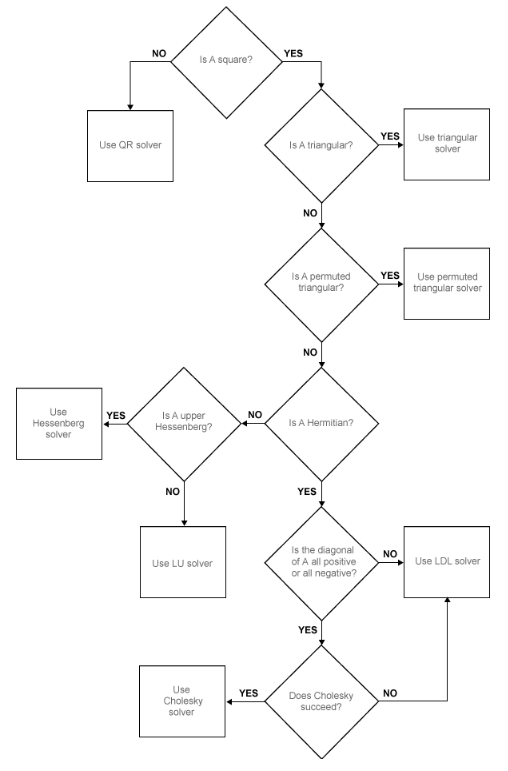

Jak widać część z tych metod nie była omawiana na wykładzie - są to metody zaawansowane niewchodzące w skład kursu adresujące konkretne problemy szczegółowe pochodzące z zagadnień praktycznych. Niemniej taką budowę mają często profesjonalne solvery i powinieneś rozumieć dlaczego tak jest. Więcej szczegółów można uzyskać wpisując do konsoli komendę 

doc \

ans = 14.2829

ans = 8

ans = 36

## NORMY

Ponieważ wynikiem rozwiązania problemu jest cały zbiór liczb (wektor rozwiązań) zatem do obliczania błędu zgodnie z definicją przyjmujemy normy wektorów.

% w MATLAB do obliczania norm służy funkcja norm()

c = [1 2 3 4 5 6 7 8];

ans =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


norm(c)

%bez podania drugiego argumentu będzie zawsze domyślnie liczona norma 2


ans =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


%Jeżeli chcemy wyliczyć inną normę musimy podać drugi argument funkcji np.

norm(c,Inf)   %obliczy normę nieskończoną
norm(c,1)     %obliczy normę pierwszą

ans =      1     1     1     1
     1     1     1     1
     1     1     1     1
     1     1     1     1


Więcej szczegółów znajdziesz wpisując w konsole komendę:

doc norm

ans =     1.5000    1.0000         0         0
    1.0000    0.5000    1.0000         0
         0    1.0000    0.5000    1.0000
         0         0    1.0000    1.5000


## **GENEROWANIE MACIERZY *****A***

W celu badania właściwości numerycznych metod często będziemy chcieli zbudować jakiś szczególny przypadek testowy układu równań. Żeby to robić sprawnie warto znać kilka funkcji generujących określone macierze. Stosując zasady składni MATLAB poznane na Lab. 0 można zazwyczaj sprawnie, nie tracąc czasu, zaimplementować wymagany układ równań. Przydatne funkcje to:

% Funkcja generująca macierz jednostkową:

eye(4)          %taki zapis wygeneruje macierz kwadratową, więcej: doc eye

ans =     1.0000    0.5000    0.3333    0.2500
    0.5000    0.3333    0.2500    0.2000
    0.3333    0.2500    0.2000    0.1667
    0.2500    0.2000    0.1667    0.1429



% Funkcja generująca macierz zer:

zeros(4)        %taki zapis wygeneruje macierz kwadratową, więcej: doc zeros


A =     1.0000    1.0000    1.0000    1.0000
    3.3750    2.2500    1.5000    1.0000
    8.0000    4.0000    2.0000    1.0000
   15.6250    6.2500    2.5000    1.0000


% Funkcja generująca macierz jedynek:

ones(4)         %taki zapis wygeneruje macierz kwadratową, więcej: doc ones


ans =     1.0000         0         0         0
    3.3750    2.2500         0         0
    8.0000    4.0000    2.0000         0
   15.6250    6.2500    2.5000    1.0000


% Funkcja generująca macierz Wilkinsona

wilkinson(4)    %taki zapis wygeneruje macierz kwadratową, więcej: doc wilkinson


ans =     1.0000    1.0000    1.0000    1.0000
         0    2.2500    1.5000    1.0000
         0         0    2.0000    1.0000
         0         0         0    1.0000


% Funkcja generująca macierz Hilberta

hilb(4)         %taki zapis wygeneruje macierz kwadratową, więcej: doc hilb

ans = 1.3294e+03


% Funkcja generująca macierz Vandermonda
% UWAGA! Ze względu na definicję tej macierzy generuje się ja z wektora!

A=vander([1:.5:2.5])      %więcej: doc vander

% Funkcja generująca macierz trójkątną dolną:
% UWAGA! Funkcja generuje macierz na podstawie istniejącej macierzy!
tril(A)

% Funckja generująca macierz trójkątną górną:

L =     1.0000         0         0
    0.3750    0.5441    1.0000
    0.5000    1.0000         0


U =     8.0000    1.0000    6.0000
         0    8.5000   -1.0000
         0         0    5.2941


% UWAGA! Funkcja generuje macierz na podstawie istniejącej macierzy!
triu(A)


Q =    -0.8480    0.5223    0.0901
   -0.3180   -0.3655   -0.8748
   -0.4240   -0.7705    0.4760


R =    -9.4340   -6.2540   -8.1620
         0   -8.2394   -0.9655
         0         0   -4.6314


% Obliczanie współczynnika uwarunkowania:
cond(A)


S =    -0.5774    0.7071    0.4082
   -0.5774    0.0000   -0.8165
   -0.5774   -0.7071    0.4082


V =    15.0000         0         0
         0    6.9282         0
         0         0    3.4641


D =    -0.5774    0.4082    0.7071
   -0.5774   -0.8165   -0.0000
   -0.5774    0.4082   -0.7071


## **ROZKŁADY**

Fakt, że MATLAB sam dobiera najbardziej optymalną metodę do danych jest przydatny praktycznie, ale utrudnia nam badanie konkretnych metod. Dlatego w trakcie laboratorium możesz zostać poproszony o zaimplementowanie konkretnej metody opierającej się o rozkład. Stosować będziemy rozkłady poznane na wykładzie, czyli:

% Przykładowa macierz A
A = magic(3);

% Rozkład LU
[L, U] = lu(A)

%Rozkład QR
[Q, R] = qr(A)

%Rozkład SVD
[S, V, D] = svd(A)
 

Po dokonaniu rozkładu resztę jawnej implementacji metody stosującej dany rozkład implementujemy za pomocą operatora wbudowanego "\". Możemy tak zrobić, ponieważ w efekcie rozkładu zawsze powstają macierze o określonych właściwościach numerycznych i w związku z tym zawsze trafią do jednej metody końcowej w drzewie wyboru operatora.

Warszawa, 11.10.2022 r.                                                                                                           **© **K. Król

Sem. 22Z